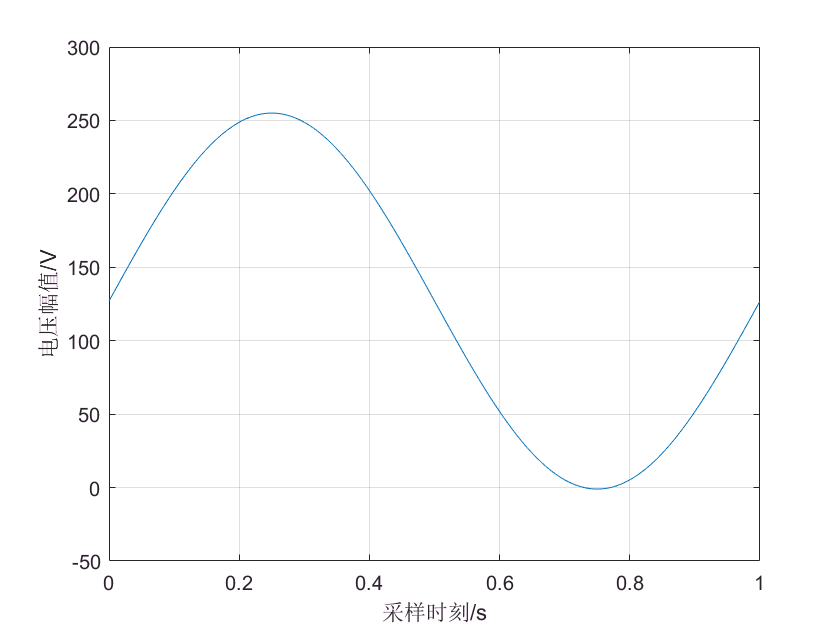

clc;
clear;

%生成信号参数
A = 2^7;  %信号幅度
F1 = 1;  %信号频率
P1 = 0;  %信号初始相位
ADC = 2^7 - 1;  %直流分量

%采样相关参数
Fs = 2^12;  %采样频率
N = 2^12;  %采样点数
t = 0 : 1 / Fs : (N - 1) / Fs;  %采样时刻


%生成正弦信号
y = A * sin(2 * pi * F1 * t + pi * P1 / 180) + ADC;
plot(t, y);
xlabel('采样时刻/s'); ylabel('电压幅值/V');
grid on;


%创建mif文件
fild = fopen('sin_wave_8x4096.mif', 'wt');

%写入mif文件头
fprintf(fild, '%s\n','WIDTH=8;');           %位宽
fprintf(fild, '%s\n\n','DEPTH=4096;');      %深度
fprintf(fild, '%s\n','ADDRESS_RADIX=UNS;'); %地址格式
fprintf(fild, '%s\n\n','DATA_RADIX=UNS;');  %数据格式
fprintf(fild, '%s\t','CONTENT');            %地址
fprintf(fild, '%s\n','BEGIN');

for i = 1 : N
    y0(i) = round(y(i));    %对小数四舍五入以取整
    if y0(i) <0;            %负1强制置零
        y0(i) = 0;
    end
    fprintf(fild, '\t%g\t', i - 1);    %地址编码
    fprintf(fild, '%s\t', ':');      %冒号
    fprintf(fild, '%d', y0(i));      %数据写入
    fprintf(fild, '%s\n', ';');      %分号，换行
end
fprintf(fild, '%s\n', 'END;');       %结束
fclose(fild);
